### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### 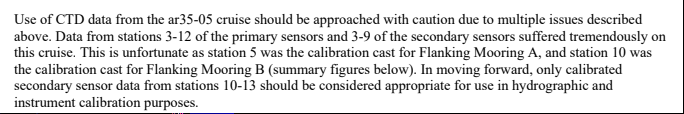

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 0 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6')
% Casts 
% cast02u = readSBScnv( 'uar35-05002.cnv' );
cast03u = readSBScnv( 'uar35-05003.cnv' );
cast04u = readSBScnv( 'uar35-05004.cnv' );
cast05u = readSBScnv( 'uar35-05005.cnv' );
cast06u = readSBScnv( 'uar35-05006.cnv' );
cast07u = readSBScnv( 'uar35-05007.cnv' );
cast08u = readSBScnv( 'uar35-05008.cnv' );
cast09u = readSBScnv( 'uar35-05009.cnv' );
cast10u = readSBScnv( 'uar35-05010.cnv' );
cast11u = readSBScnv( 'uar35-05011.cnv' );
cast12u = readSBScnv( 'uar35-05012.cnv' );
cast13u = readSBScnv( 'uar35-05013.cnv' );

% cast02d = readSBScnv( 'dar35-05002.cnv' );
cast03d = readSBScnv( 'dar35-05003.cnv' );
cast04d = readSBScnv( 'dar35-05004.cnv' );
cast05d = readSBScnv( 'dar35-05005.cnv' );
cast06d = readSBScnv( 'dar35-05006.cnv' );
cast07d = readSBScnv( 'dar35-05007.cnv' );
cast08d = readSBScnv( 'dar35-05008.cnv' );
cast09d = readSBScnv( 'dar35-05009.cnv' );
cast10d = readSBScnv( 'dar35-05010.cnv' );
cast11d = readSBScnv( 'dar35-05011.cnv' );
cast12d = readSBScnv( 'dar35-05012.cnv' );
cast13d = readSBScnv( 'dar35-05013.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6\Final_From_Leah')
load ar35-05_final.mat

% Combine leah's finalized product with my oxygen file
% function [cast,cast0] = combine_CTD_files_Aanderaa(leah_cast,cast)

[cast03u, ~] = combine_CTD_files_Aanderaa(ar35_003u,cast03u); [cast03d, ~] = combine_CTD_files_Aanderaa(ar35_003d,cast03d);  
[cast04u, ~] = combine_CTD_files_Aanderaa(ar35_004u,cast04u); [cast04d, ~] = combine_CTD_files_Aanderaa(ar35_004d,cast04d);  
[cast05u, ~] = combine_CTD_files_Aanderaa(ar35_005u,cast05u); [cast05d, ~] = combine_CTD_files_Aanderaa(ar35_005d,cast05d);  
[cast06u, ~] = combine_CTD_files_Aanderaa(ar35_006u,cast06u); [cast06d, ~] = combine_CTD_files_Aanderaa(ar35_006d,cast06d);  
[cast07u, ~] = combine_CTD_files_Aanderaa(ar35_007u,cast07u); [cast07d, ~] = combine_CTD_files_Aanderaa(ar35_007d,cast07d);  
[cast08u, ~] = combine_CTD_files_Aanderaa(ar35_008u,cast08u); [cast08d, ~] = combine_CTD_files_Aanderaa(ar35_008d,cast08d);  
[cast09u, ~] = combine_CTD_files_Aanderaa(ar35_009u,cast09u); [cast09d, ~] = combine_CTD_files_Aanderaa(ar35_009d,cast09d);  
[cast10u, ~] = combine_CTD_files_Aanderaa(ar35_010u,cast10u); [cast10d, ~] = combine_CTD_files_Aanderaa(ar35_010d,cast10d);  
[cast11u, ~] = combine_CTD_files_Aanderaa(ar35_011u,cast11u); [cast11d, ~] = combine_CTD_files_Aanderaa(ar35_011d,cast11d);  
[cast12u, ~] = combine_CTD_files_Aanderaa(ar35_012u,cast12u); [cast12d, ~] = combine_CTD_files_Aanderaa(ar35_012d,cast12d);  
[cast13u, ~] = combine_CTD_files_Aanderaa(ar35_013u,cast13u); [cast13d, ~] = combine_CTD_files_Aanderaa(ar35_013d,cast13d);

### Create bottle summary file with Leah's calibrated bottle file


addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year6')
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6\Final_From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6')

btl = readtable('Irminger_Sea-06_AR35-05_Discrete_Summary_KF.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);

btlsum11 = combine_btl_files_Aanderaa('ar35-05_011.cbot_so','ar35-05011.csv',btlsum11);

btlsum12 = combine_btl_files_Aanderaa('ar35-05_012.cbot_so','ar35-05012.csv',btlsum12);

btlsum13 = combine_btl_files_Aanderaa('ar35-05_013.cbot_so','ar35-05013.csv',btlsum13);

### Combine cast and bottle files with Leah's final product. Clean up and organize variables into tables. 

CTD_sen2 = 2; 

%THESE COEFFICIENTS ARE DIFFERENT FOR EACH OPTODE - they are found on the
%calibration certificate sheet
%You will need to update for specific sensor used - this is for SN502
%You should also check the salinity setting for the sensor - if it is
%something other than zero, the final line of this function will need to be
%modified

% foilcoeff = [2.798512E-03       1.179460E-04    2.512907E-06    2.262806E+02    -3.570254E-01   -6.104725E+01   4.558537E+00];
% conccoeff = [0.000000E+00 1.160000E+00];

% [castu, castd, btlsum] = Process_Cast_Aanderaa(castu,castd,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast03u, cast03d, btlsum03] = Process_Cast_Aanderaa(cast03u,cast03d,0,CTD_sen2,'Cast 03');
[cast04u, cast04d, btlsum04] = Process_Cast_Aanderaa(cast04u,cast04d,0,CTD_sen2,'Cast 04');
[cast05u, cast05d, btlsum05] = Process_Cast_Aanderaa(cast05u,cast05d,0,CTD_sen2,'Cast 05');
[cast06u, cast06d, btlsum06] = Process_Cast_Aanderaa(cast06u,cast06d,0,CTD_sen2,'Cast 06');
[cast07u, cast07d, btlsum07] = Process_Cast_Aanderaa(cast07u,cast07d,0,CTD_sen2,'Cast 07');
[cast08u, cast08d, btlsum08] = Process_Cast_Aanderaa(cast08u,cast08d,0,CTD_sen2,'Cast 08');
[cast09u, cast09d, btlsum09] = Process_Cast_Aanderaa(cast09u,cast09d,0,CTD_sen2,'Cast 09');
[cast10u, cast10d, btlsum10] = Process_Cast_Aanderaa(cast10u,cast10d,0,CTD_sen2,'Cast 10'); 
[cast11u, cast11d, btlsum11] = Process_Cast_Aanderaa(cast11u,cast11d,btlsum11,CTD_sen2,'Cast 11');
[cast12u, cast12d, btlsum12] = Process_Cast_Aanderaa(cast12u,cast12d,btlsum12,CTD_sen2,'Cast 12');
[cast13u, cast13d, btlsum13] = Process_Cast_Aanderaa(cast13u,cast13d,btlsum13,CTD_sen2,'Cast 13');

### Calculate and apply time lag for Aanderaa optode 

Calculated in depth space because RMSDs lower than by calculating in density space 

[ Gordon2020_03, cast03d, cast03u] = Aanderaa_timelag(cast03d,cast03u,[1000 2000]);
[ Gordon2020_04, cast04d, cast04u] = Aanderaa_timelag(cast04d,cast04u,[100 600]);
[ Gordon2020_05, cast05d, cast05u] = Aanderaa_timelag(cast05d,cast05u,[1000 2000]);
[ Gordon2020_06, cast06d, cast06u] = Aanderaa_timelag(cast06d,cast06u,[1000 2000]);
[ Gordon2020_07, cast07d, cast07u] = Aanderaa_timelag(cast07d,cast07u,[1000 2000]);
[ Gordon2020_08, cast08d, cast08u] = Aanderaa_timelag(cast08d,cast08u,[100 600]);
[ Gordon2020_09, cast09d, cast09u] = Aanderaa_timelag(cast09d,cast09u,[1000 2000]);
[ Gordon2020_10, cast10d, cast10u] = Aanderaa_timelag(cast10d,cast10u,[1000 2000]);
[ Gordon2020_11, cast11d, cast11u] = Aanderaa_timelag(cast11d,cast11u,[1000 2000]);
[ Gordon2020_12, cast12d, cast12u] = Aanderaa_timelag(cast12d,cast12u,[1000 2000]);
[ Gordon2020_13, cast13d, cast13u] = Aanderaa_timelag(cast13d,cast13u,[1000 2000]);

% thickness = [Gordon2020_03.thicknessz Gordon2020_03.thicknessd
% Gordon2020_04.thicknessz Gordon2020_04.thicknessd
% Gordon2020_05.thicknessz Gordon2020_05.thicknessd
% Gordon2020_06.thicknessz Gordon2020_06.thicknessd
% Gordon2020_07.thicknessz Gordon2020_07.thicknessd
% Gordon2020_08.thicknessz Gordon2020_08.thicknessd
% Gordon2020_09.thicknessz Gordon2020_09.thicknessd
% Gordon2020_10.thicknessz Gordon2020_10.thicknessd
% Gordon2020_11.thicknessz Gordon2020_11.thicknessd
% Gordon2020_12.thicknessz Gordon2020_12.thicknessd
% Gordon2020_13.thicknessz Gordon2020_13.thicknessd];
% 
% nanmean(thickness)
% nanstd(thickness)
% 
% tau_Tref = [Gordon2020_03.tau_Trefz Gordon2020_03.tau_Trefd
% Gordon2020_04.tau_Trefz Gordon2020_04.tau_Trefd
% Gordon2020_05.tau_Trefz Gordon2020_05.tau_Trefd
% Gordon2020_06.tau_Trefz Gordon2020_06.tau_Trefd
% Gordon2020_07.tau_Trefz Gordon2020_07.tau_Trefd
% Gordon2020_08.tau_Trefz Gordon2020_08.tau_Trefd
% Gordon2020_09.tau_Trefz Gordon2020_09.tau_Trefd
% Gordon2020_10.tau_Trefz Gordon2020_10.tau_Trefd
% Gordon2020_11.tau_Trefz Gordon2020_11.tau_Trefd
% Gordon2020_12.tau_Trefz Gordon2020_12.tau_Trefd
% Gordon2020_13.tau_Trefz Gordon2020_13.tau_Trefd];
% 
% nanmean(tau_Tref)
% nanstd(tau_Tref)
% 
% rmsdz = [Gordon2020_03.rmsdz 
% Gordon2020_04.rmsdz
% Gordon2020_05.rmsdz
% Gordon2020_06.rmsdz
% Gordon2020_07.rmsdz 
% Gordon2020_08.rmsdz 
% Gordon2020_09.rmsdz
% Gordon2020_10.rmsdz 
% Gordon2020_11.rmsdz
% Gordon2020_12.rmsdz 
% Gordon2020_13.rmsdz];
% 
% rmsdd = [Gordon2020_03.rmsdd 
% Gordon2020_04.rmsdd
% Gordon2020_05.rmsdd
% Gordon2020_06.rmsdd
% Gordon2020_07.rmsdd 
% Gordon2020_08.rmsdd 
% Gordon2020_09.rmsdd
% Gordon2020_10.rmsdd 
% Gordon2020_11.rmsdd
% Gordon2020_12.rmsdd 
% Gordon2020_13.rmsdd];

thickness = [Gordon2020_03.thickness
% Gordon2020_04.thickness
Gordon2020_05.thickness
Gordon2020_06.thickness
Gordon2020_07.thickness
Gordon2020_08.thickness
Gordon2020_09.thickness
Gordon2020_10.thickness
Gordon2020_11.thickness
Gordon2020_12.thickness
Gordon2020_13.thickness];

mean(thickness)

ans = 14.9000

median(thickness)

ans = 15

std(thickness)

ans = 8.9994


tau_Tref = [Gordon2020_03.tau_Tref
Gordon2020_04.tau_Tref
Gordon2020_05.tau_Tref
Gordon2020_06.tau_Tref
Gordon2020_07.tau_Tref
Gordon2020_08.tau_Tref
Gordon2020_09.tau_Tref
Gordon2020_10.tau_Tref
Gordon2020_11.tau_Tref
Gordon2020_12.tau_Tref
Gordon2020_13.tau_Tref];

mean(tau_Tref)

ans = 10.1051

median(tau_Tref)

ans = 9.9745

std(tau_Tref)

ans = 4.5724

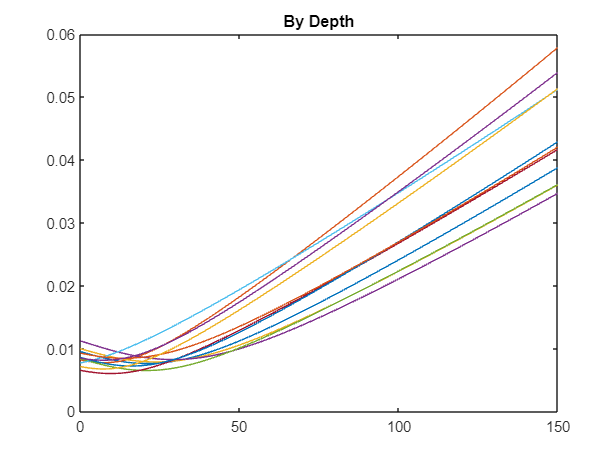


rmsd = [Gordon2020_03.rmsd 
Gordon2020_04.rmsd
Gordon2020_05.rmsd
Gordon2020_06.rmsd
Gordon2020_07.rmsd 
Gordon2020_08.rmsd 
Gordon2020_09.rmsd
Gordon2020_10.rmsd 
Gordon2020_11.rmsd
Gordon2020_12.rmsd 
Gordon2020_13.rmsd];

figure
plot(Gordon2020_03.thickness_constants,rmsd)
title('By Depth')

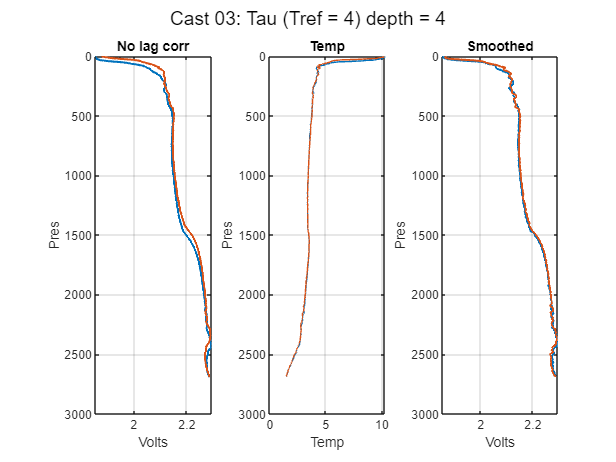

tau.thickness = 30; 
% tau.thickness = 10.2; 
tau.tau_Tref = 4;

[cast03d, cast03u] = correct_Aanderaa_profiles(cast03d,cast03u,tau,'Cast 03');

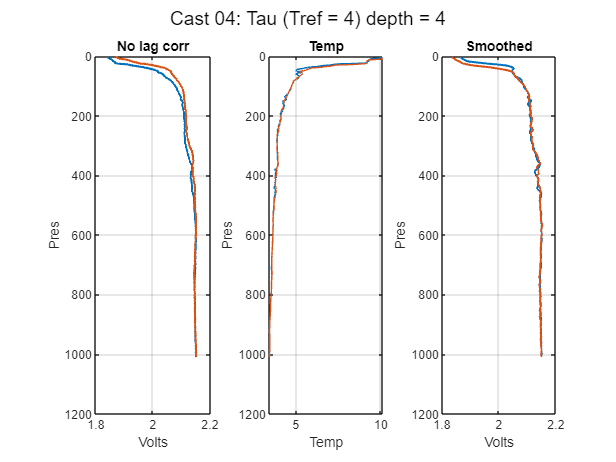

[cast04d, cast04u] = correct_Aanderaa_profiles(cast04d,cast04u,tau,'Cast 04');

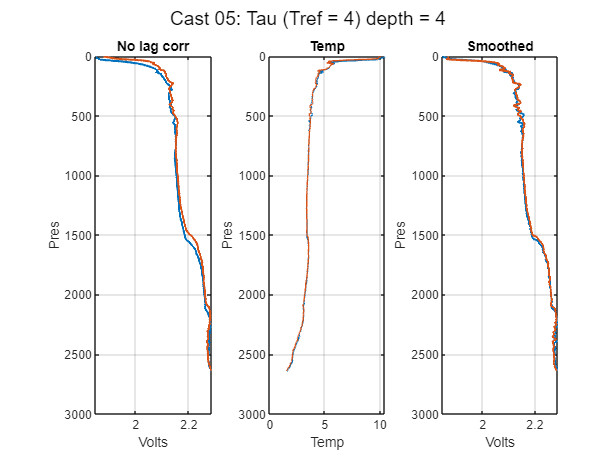

[cast05d, cast05u] = correct_Aanderaa_profiles(cast05d,cast05u,tau,'Cast 05');

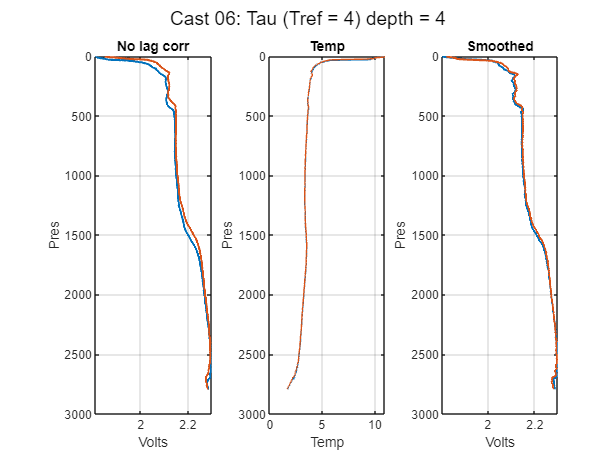

[cast06d, cast06u] = correct_Aanderaa_profiles(cast06d,cast06u,tau,'Cast 06');

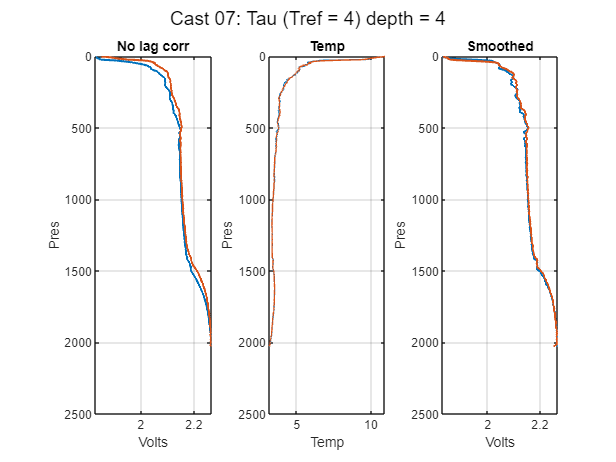

[cast07d, cast07u] = correct_Aanderaa_profiles(cast07d,cast07u,tau,'Cast 07');

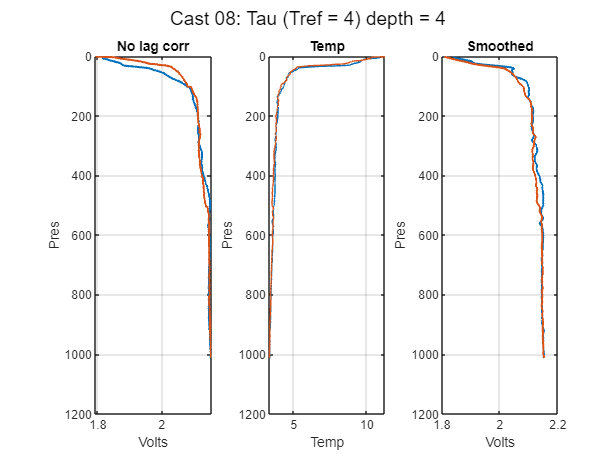

[cast08d, cast08u] = correct_Aanderaa_profiles(cast08d,cast08u,tau,'Cast 08');

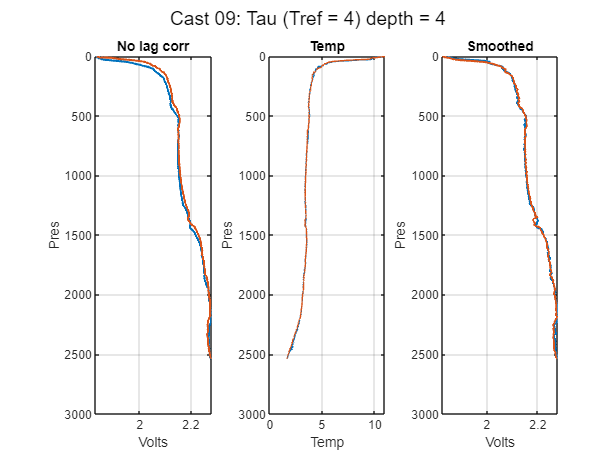

[cast09d, cast09u] = correct_Aanderaa_profiles(cast09d,cast09u,tau,'Cast 09');

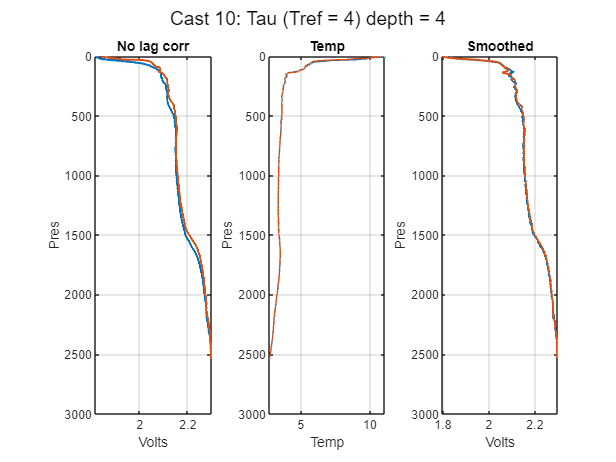

[cast10d, cast10u] = correct_Aanderaa_profiles(cast10d,cast10u,tau,'Cast 10');

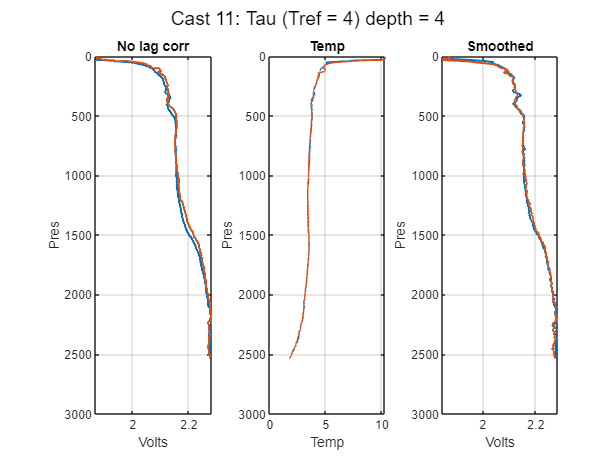

[cast11d, cast11u] = correct_Aanderaa_profiles(cast11d,cast11u,tau,'Cast 11');

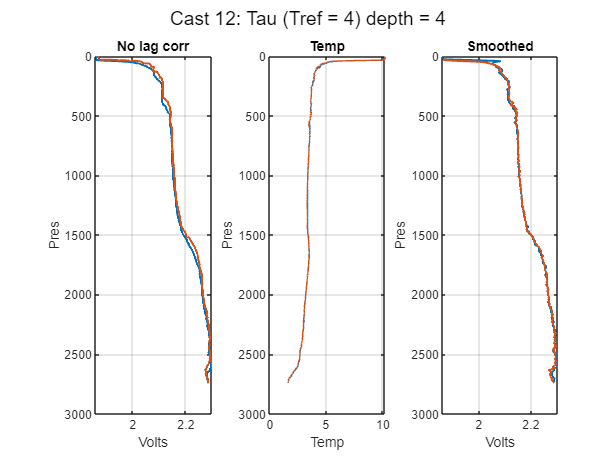

[cast12d, cast12u] = correct_Aanderaa_profiles(cast12d,cast12u,tau,'Cast 12');

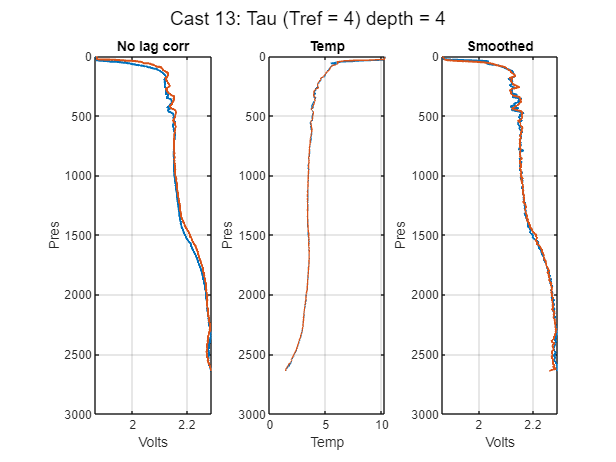

[cast13d, cast13u] = correct_Aanderaa_profiles(cast13d,cast13u,tau,'Cast 13');

### Pull out time lag corrected cast data for bottle file/Winkler comparison  (gain correction)

% From Aanderaa calibration file for SN 502 
foilcoeff502 = [2.82567E-3 1.20716E-4 2.4593E-6 2.30757E2 -3.09502E-1 -5.60627E1 4.5615E0];
conccoeff502 = [-1.285961 1.039998];
salset502 = 0;  % salinity set at 0  
btlsum13.prs(1) = floor(btlsum13.prs(1)); % Need to round down for deepest bin 

[btlsum11] = Aanderaa_gain_btl(cast11u,btlsum11,foilcoeff502,conccoeff502,salset502);
[btlsum12] = Aanderaa_gain_btl(cast12u,btlsum12,foilcoeff502,conccoeff502,salset502);
[btlsum13] = Aanderaa_gain_btl(cast13u,btlsum13,foilcoeff502,conccoeff502,salset502);


btlgain = [btlsum11.gain; btlsum12.gain; btlsum13.gain];
% btlgaind = [btlsum11.gaind; btlsum12.gaind; btlsum13.gaind];

gain_mean = nanmean(btlgain)

gain_mean = 1.0032

gain_std = nanstd(btlgain)

gain_std = 0.0126


% gaind = nanmean(btlgaind)
% stdd = nanstd(btlgaind)

gain502 = gain_mean;

% [castu, castd, btlsum] = Process_Cast_Aanderaa(castu,castd,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast03u, cast03d, btlsum03] = Aanderaa_gain_cast(cast03u,cast03d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 03');

Unrecognized function or variable 'heigth'.

Error in Aanderaa_gain_cast (line 22)
if heigth(btlsum ) ~= 1

[cast04u, cast04d, btlsum04] = Aanderaa_gain_cast(cast04u,cast04d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 04');
[cast05u, cast05d, btlsum05] = Aanderaa_gain_cast(cast05u,cast05d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 05');
[cast06u, cast06d, btlsum06] = Aanderaa_gain_cast(cast06u,cast06d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 06');
[cast07u, cast07d, btlsum07] = Aanderaa_gain_cast(cast07u,cast07d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 07');
[cast08u, cast08d, btlsum08] = Aanderaa_gain_cast(cast08u,cast08d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 08');
[cast09u, cast09d, btlsum09] = Aanderaa_gain_cast(cast09u,cast09d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 09');
[cast10u, cast10d, btlsum10] = Aanderaa_gain_cast(cast10u,cast10d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 10'); 
[cast11u, cast11d, btlsum11] = Aanderaa_gain_cast(cast11u,cast11d,btlsum11,foilcoeff502,conccoeff502,salset502,gain502,'Cast 11');
[cast12u, cast12d, btlsum12] = Aanderaa_gain_cast(cast12u,cast12d,btlsum12,foilcoeff502,conccoeff502,salset502,gain502,'Cast 12');
[cast13u, cast13d, btlsum13] = Aanderaa_gain_cast(cast13u,cast13d,btlsum13,foilcoeff502,conccoeff502,salset502,gain502,'Cast 13');

% run('Year6_PT_DO_plots.m')

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6')
% clear btlsum0
% dt_Processed = datetime;
% save Year6_Processed_KF cast* btl* cal* dt_Processed 